## **CSE 250A HW-1**

### **Problem 1.5: Kullback-Leibler Distance**

**(a) Plot the function.**

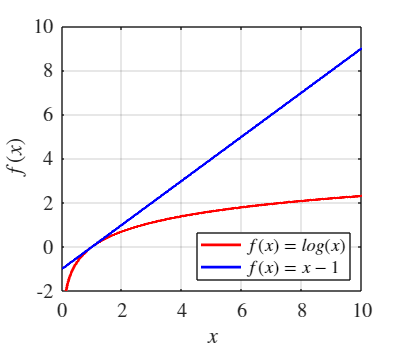

% Plot settings.
set(0, 'DefaultAxesFontSize', 15);
set(0, 'DefaultTextFontSize', 15);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

% Plot the function.
x = 0:0.01:10;

figure('Position', [0, 0, 400, 350]);
hold on;
plot(x, log(x), 'Color', 'r', 'LineWidth', 2);
plot(x, x-1, 'Color', 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 10]);
xticks(0:2:10);
ylim([-2 10]);
yticks(-2:2:10);
xlabel('$x$');
ylabel('$f(x)$');
legend('$f(x)=log(x)$', '$f(x)=x-1$', 'Location', 'southeast');

### **Problem 1.7: Hangman**

**(a) Read the word list and compute the prior probability, then print out the 15 most frequent and the 14 least frequent 5-letter words.**

*Initialization and read word list file:*

% Obtain the name and path of the word list file.
% "uigetfile" command: Open a dialog box that lists files with particular file type in the current folder.
[FileName, FolderName, FilterIndex] = uigetfile('*.txt');
FullFileName = fullfile(FolderName, FileName); % fullfile(folder, subfolder, file).

% Open the file based on the given file name and returns to an integer file identifier equal to or greater than 3.
% "fopen" command: FileID = fopen(filename, permission). 'r' represents read only.
WordListFile = fopen(FullFileName, 'r');

% Read the word list and convert it into a table.
WordList = textscan(WordListFile, '%s %d', 'Delimiter', ' ');
WordList = table(cell2mat(WordList{1}), WordList{2}, 'VariableNames', {'Word', 'Count'});

% Close the word list file.
fclose(WordListFile);

*Compute the prior probability:*

% Note: At least one operand should be double type in division.
% Therefore, floating-point division is performed instead of integer division.
WordList.Probability = double(WordList{:,2})/sum(WordList{:,2});

*Find and print the 15 most frequent words:*

% Find the 15 largest frequencies from the 2nd column in the word list and their corresponding row indices.
[MaxFreqs, MaxIndices] = maxk(WordList{:,2}, 15); % [MaxValues, Indices] = maxk(Vector, NumberOfValues).

% Save the rows corresponding to the 15 largest frequencies to a table.
WordsMaxFreq = WordList(MaxIndices,:);
disp(WordsMaxFreq);

    Word     Count     Probability
    _____    ______    ___________

    THREE    273077      0.035627 
    SEVEN    178842      0.023333 
    EIGHT    165764      0.021626 
    WOULD    159875      0.020858 
    ABOUT    157448      0.020542 
    THEIR    145434      0.018974 
    WHICH    142146      0.018545 
    AFTER    110102      0.014365 
    FIRST    109957      0.014346 
    FIFTY    106869      0.013943 
    OTHER    106052      0.013836 
    FORTY     94951      0.012388 
    YEARS     88900      0.011598 
    THERE     86502      0.011286 
    SIXTY     73086     0.0095352 



*Find and print the 14 least frequent words:*

% Find the 14 smallest frequencies from the 2nd column in the word list and their corresponding row indices.
[MinFreqs, MinIndices] = mink(WordList{:,2}, 14); % [MinValues, Indices] = mink(Vector, NumberOfValues).

% Save the rows corresponding to the 14 smallest frequencies to a table.
WordsMinFreq = WordList(MinIndices,:);
disp(WordsMinFreq);

    Word     Count    Probability
    _____    _____    ___________

    BOSAK      6      7.8279e-07 
    CAIXA      6      7.8279e-07 
    MAPCO      6      7.8279e-07 
    OTTIS      6      7.8279e-07 
    TROUP      6      7.8279e-07 
    CCAIR      7      9.1326e-07 
    CLEFT      7      9.1326e-07 
    FABRI      7      9.1326e-07 
    FOAMY      7      9.1326e-07 
    NIAID      7      9.1326e-07 
    PAXON      7      9.1326e-07 
    SERNA      7      9.1326e-07 
    TOCOR      7      9.1326e-07 
    YALOM      7      9.1326e-07 



The results make sense since the most frequent words represent numbers or some commonly used words, and I have never seen any one of the 14 least frequent words ever before.

**(b) Find the best next guess and report the corresponding probability.**

*Case 1:*

% Input the evidence.
TrueEvidence = table([ ], [ ], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = ' ';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: E
Probability: 0.53942


*Case 2:*

% Input the evidence.
TrueEvidence = table([ ], [ ], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = 'EA';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: O
Probability: 0.53403


*Case 3:*

% Input the evidence.
TrueEvidence = table(['A'; 'S'], [1; 5], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = ' ';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: E
Probability: 0.77154


*Case 4:*

% Input the evidence.
TrueEvidence = table(['A'; 'S'], [1; 5], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = 'I';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: E
Probability: 0.7127


*Case 5:*

% Input the evidence.
TrueEvidence = table(['O'; 'O'], [3; 3], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = 'AEMNT';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: R
Probability: 0.74539


*Case 6:*

% Input the evidence.
TrueEvidence = table([], [], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = 'EO';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: I
Probability: 0.63656


*Case 7:*

% Input the evidence.
TrueEvidence = table(['D'; 'I'], [1; 4], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = ' ';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: A
Probability: 0.82068


*Case 8:*

% Input the evidence.
TrueEvidence = table(['D'; 'I'], [1; 4], 'VariableNames', {'Letter', 'Index'});
FalseEvidence = 'A';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: E
Probability: 0.75207


*Case 9:*

% Input the evidence.
TrueEvidence = table(['U'; 'U'], [2; 2], 'VariableNames', {'Letter', 'Index'});

FalseEvidence = 'AEIOS';

% Calculate and report the best next guess and report the corresponding probability.
[BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList);

Best next guess: Y
Probability: 0.62697


*Hangman function*:

function [BestGuess, MaxProbability] = Hangman(TrueEvidence, FalseEvidence, WordList)
% Input:
% 1. TrueEvidence (nx2) = Correctly guessed letters (column 1) and the correponding indices (column 2).
% 2. FalseEvidence (1xn) = Incorrectly guessed letters.
% 3. WordList = All the word list including counts and prior probabilities.
% Output:
% BestGuess = Best guess of the letter.
% MaxProbablity = Probability that the best guess is correct.

% Evidence check: Find all the possible words that satisfies the given evidence.
% Initialize evidence mask values for all the words as 1.
EvidenceMask = ones(size(WordList, 1), 1);

for WordIndex = 1:size(WordList, 1) % Loop over all the possible words.
    % Evidence check 1: Check correctly guessed letters appear at correct indices.
    for TrueEvidenceIndex = 1:size(TrueEvidence, 1) % Loop over each correctly guessed letters.
        % If the word can match the correct guess, keep the previous mask value.
        if WordList{WordIndex, 1}(TrueEvidence{TrueEvidenceIndex, 2}) == TrueEvidence{TrueEvidenceIndex,1} 
            EvidenceMask(WordIndex) = EvidenceMask(WordIndex); 
        % If the word can not match the correct guess, set the mask value to 0.
        else
            EvidenceMask(WordIndex) = 0;
        end
    end
    
    % Evidence check 2: Check correctly guessed letters or incorrectly guessed letters do not appear at any other indices.
    if EvidenceMask(WordIndex, 1) == 1
        % Create a sub-word after removing correctly guessed letters (at correct indices).
        SubWord = WordList{WordIndex, 1};
        SubWord(TrueEvidence{:,2}) = [];
        % If any correctly guessed letters or incorrectly guessed letters appear at any other indices, set the mask value to 0.
        if any(ismember(SubWord, [TrueEvidence{:,1}; FalseEvidence']))
            EvidenceMask(WordIndex) = 0;
        end
    end
end

% Initialization for the candidate word list as an empty table.
CandidateWordList = table([], [], 'VariableNames', {'Word', 'Count'});

% Generate the candidate word list.
for WordIndex = 1:size(WordList, 1)
    if EvidenceMask(WordIndex) == 1
        CandidateWordList = [CandidateWordList; {WordList{WordIndex, 1}, WordList{WordIndex, 2}}];
    end
end

% Create a list for all the letters except those have been correctly guessed.
LetterList = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';
RemovedIndices = zeros(size(TrueEvidence, 1), 1);

for TrueEvidenceIndex = 1:size(TrueEvidence, 1) % Loop over each correctly guessed letters.
    RemovedIndices(TrueEvidenceIndex) = find(LetterList == TrueEvidence{TrueEvidenceIndex, 1});
end

LetterList(RemovedIndices) = [];

% Initialization of a matrix for the count of letters in the candidate letter list.
LetterCount = zeros(size(CandidateWordList, 1) , size(LetterList, 2));

% Caculate the letter count matrix.
for WordIndex = 1:size(CandidateWordList, 1)
    for LetterIndex = 1:size(LetterList, 2)
        if contains(CandidateWordList{WordIndex, 1}, LetterList(LetterIndex))
            LetterCount(WordIndex, LetterIndex) = LetterCount(WordIndex, LetterIndex) + 1;
        end
    end
end

% Update the letter count considering the number of each word.
LetterCount = LetterCount .* double(CandidateWordList{:,2});

% Calcuate the correct guess probability for each letter.
Probability = sum(LetterCount)/sum(CandidateWordList{:, 2});

% Obtain the maximum probability and the corresponding index for the letter.
[MaxProbability, MaxLetterIndex] = max(Probability);

% Select the letter corresponding to the maximum probability as the best guess.
BestGuess = LetterList(MaxLetterIndex);

disp(['Best next guess: ', BestGuess]);
disp(['Probability: ', num2str(MaxProbability)]);
    
end